# EE525 - Project 3

Author: Grant Gallagher

## Initialization

% clc;
% clear;

## 1. FIR and IIR Filters

Consider a white Gaussian discrete-time random process X[n] with amplitude of 1 as input to the following filter

$y\left\lbrack n\right\rbrack =x\left\lbrack n\right\rbrack -x\left\lbrack n-1\right\rbrack +x\left\lbrack n-2\right\rbrack$ (1)

### 1.1 Simulated Solution

 Simulate the random process $X\left\lbrack n\right\rbrack$ by a series of $N=50000$ samples that are i.i.d. and generated from Gaussian random variables with zero mean and unit variance.  Verify that the simulated sequence is white noise analytically and experimentally.

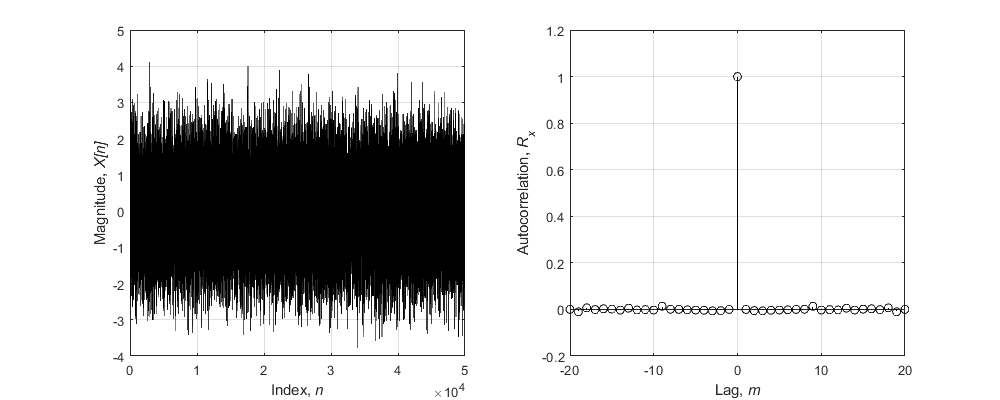

N = 50000; % Sequence size
X = normrnd(0,1,[1 N]); % Generate Gaussian random sequence
Rx = autocorrelation(X); % Evaluate autocorrelation sequence

fig1 = figure('Position',[0 0 1000 400]);

subplot(1,2,1) % Subplot of random sample sequence
plot(X,'Color','Black')
xlabel('Index, {\itn}')
ylabel('Magnitude, {\itX[n]}')
grid on
box on

subplot(1,2,2) % Subplot of autocorrelation sequence
plotR(Rx)
xlabel('Lag, {\itm}')
ylabel('Autocorrelation, {\itR_x}')
ylim([-0.2 1.2])
grid on
box on
saveas(fig1,'fig1.png')

### 1.2 Filter the Random Sequence

b = [1 -1 1];      % Numerator coefficients
a = [1];           % Denominator coefficients
Y = filter(b,a,X); % Output of filtered random sequence

#### **1.2.1 Plot the PDF**

fig2 = figure('Position',[0 0 500 400]);
nu_Y = average(Y)

nu_Y = 0.0094

sY = variance(Y).^(1/2)

sY = 1.7281

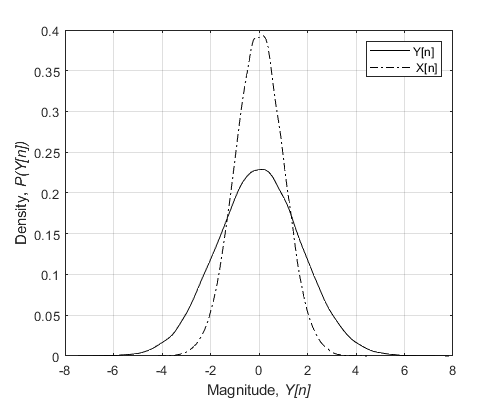


hold on
[f, Yi] = ksdensity(Y);
plot(Yi,f,'Color','Black')

[f, Xi] = ksdensity(X);
plot(Xi,f,'-.','Color','Black')
hold off


xlabel('Magnitude, {\itY[n]}')
ylabel('Density, {\itP(Y[n])}')
legend('Y[n]', ' X[n]')
xlim([-8 8])
grid on
box on

#### 1.2.2 Draw 4 Scatterplots

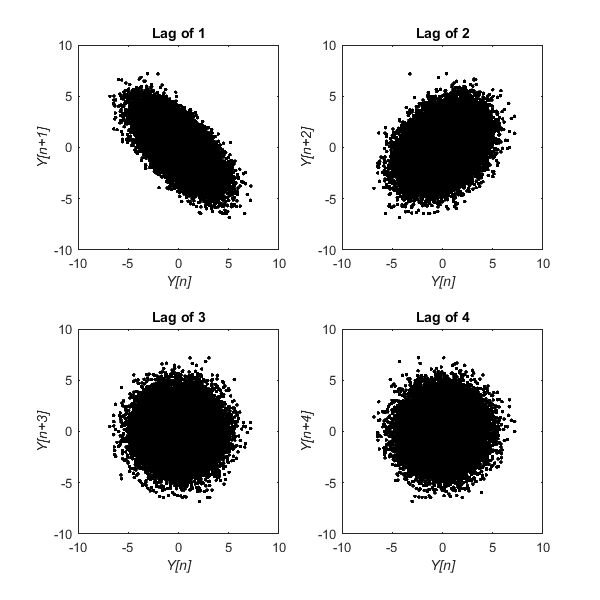

fig3 = figure('Position',[0 0 600 600]);
subplot(2,2,1);
plot(Y(1:end-1), Y(2:end),'.','Color',[0 0 0])
xlabel('{\itY[n]}')
ylabel('{\itY[n+1]}')
title('Lag of 1')
subplot(2,2,2);
plot(Y(1:end-2), Y(3:end),'.','Color',[0 0 0])
xlabel('{\itY[n]}')
ylabel('{\itY[n+2]}')
title('Lag of 2')
subplot(2,2,3);
plot(Y(1:end-3), Y(4:end),'.','Color',[0 0 0])
xlabel('{\itY[n]}')
ylabel('{\itY[n+3]}')
title('Lag of 3')
subplot(2,2,4);
plot(Y(1:end-4), Y(5:end),'.','Color',[0 0 0])
xlabel('{\itY[n]}')
ylabel('{\itY[n+4]}')
title('Lag of 4')

return

### 1.3 Autocorrelation

x = zeros(1,N);
y = zeros(1,N);
K = 100;
X = zeros(K,N);
Y = zeros(K,N);
for s = 1:K
    X(s,:) = randn([1 N]);
    % Y(s,:) = cos(2*pi/1000*linspace(1,N,N)).*(1+X(s,:));
    Y(s,:) = filter(b, a, X(s,:));
end
for n = 1:N
    x(n) = average(X(:,n));
    y(n) = average(Y(:,n));
end

Ry = autocorrelation(y);
figure;
plotR(Ry)
grid on

### 1.4 Power Spectral Density Function

Sample Dataset

% x = [1:10000]
% % y = 5*cos(2*pi/50*x) + randn(1,length(x))
% % N = length(x)
% plot(y)
% xlim([0 36])

FFT of raw output data

figure('Position',[0 0 800 800]);
subplot(4,1,1)
Fy = (abs(fft(y)).^2)/N;
P2 = abs(Fy); 
P1 = P2(1:N/2+1);
P1(2:end-1) = P1(2:end-1);
f = (0:N/2)/N;
plot(f,10*log10(P1/2),'Color','Black') 
xlabel('Sample Frequency, {\itf} [cycles/sample]')
ylabel('Power Spectral Density, {\itP}')
title('DTFT of Output Data')
grid on

FFT of aucorrelation Function

subplot(4,1,2)
Fy = fft(Ry);
P2 = abs(Fy);
P1 = P2(1:N/2+1);
P1(2:end-1) = P1(2:end-1);
f = (0:N/2)/N;
plot(f, 10*log10(P1))
title('Estimated Periodogram (FFT of Autocorrelation)')
grid on


Periodogram of output data (To check answer)

subplot(4,1,3)
[Py, w] = periodogram(y);
plot(w/(2*pi),10*log10(Py))
xlabel('Sample Frequency, {\itf} [cycles/sample]')
ylabel('Power Spectral Density, {\itP}')
title('Periodogram (Corrected Units)')
grid on



subplot(4,1,4)
periodogram(y)

figure;
pwelch(y);

- Filter $X\left\lbrack n\right\rbrack$ using (1).  Note you can use filter() in MATLAB to generate the output sequence $Y\left\lbrack n\right\rbrack$.

- Plot the probability density function of Y[i], i=1,2,..., N. Explain the results.

- Draw 4 scatter plots using subplot(22n), n=1,2,3,4. The first scatter plot should consist of points (Y[i], Y [i +1]). This correlates samples that are separated by a lag of “1”. The other 3 scatter plots should consist of points (Y[i], Y [i +2]), (Y[i], Y [i+3]), (Y[i], Y [i +4]), I = 1, 2, ..., N-10, respectively. What can you conclude about the output random process from all the plots?

- Evaluate the autocorrelation function RY[m] from the sample autocorrelation of Y[n]. Plot both the theoretical autocorrelation and the sample autocorrelation versus 𝑚𝑚 for  −20≤𝑚𝑚≤20. Note it is necessary to take the ensemble average of the function of interest.  Explain any discrepancies.

- Evaluate the power spectral density function of Y[n]   by (a) periodogram (don’t use the built-in function), and (b) DTFT of the autocorrelation function. Note these may be evaluated using fft() from MATLAB. To get reasonable results, it is necessary to take the ensemble average of the functions of interest. Again compare these with the theoretical results and explain any discrepancies.

- Is there any relationship between the input and output PSDs? Why or why not?

- Repeat steps 2-5 with the following system

$y\left\lbrack n\right\rbrack -0\ldotp 95y\left\lbrack n-1\right\rbrack =x\left\lbrack n\right\rbrack$ (2)

## Mean Function

function mu = average(S)
    mu = sum(S)/length(S);
end

### Variance Function

function sigma_2 = variance(S)
    sigma_2 = sum((S-average(S)).^2)/(length(S)-1);
end

### Autocorrelation Function

function R = autocorrelation(sample)
    N = length(sample);
    R = zeros(length(N), 1);
    sample_avg = average(sample);
    for n = 0:N-1
        sum1 = 0;
        sum2 = 0;
        for k = 1:(N-n)
            sum1 = sum1 + (sample(k)-sample_avg)*(sample(k+n)-sample_avg);
            sum2 = sum2 + (sample(k)-sample_avg)^2;
        end
        R(n+1) = sum1/sum2;
    end
    R = R';  
end

### Plot Autocorrelation

function plotR(R)
    R_positive = R(2:end);
    R_negative = flip(R_positive);
    
    Ry_plot = [R_negative; R(1); R_positive];
    indices = linspace(-(length(R)-1),(length(R)-1),length(R)*2-1);
    
    stem(indices, Ry_plot,'Color',[0 0 0])    
    xlim([-20 20])
end